# Sustitución 

[⇦ Menú principal](matlab:open('MainMenu.mlx'))

Una comprensión profunda de la integral como antiderivada sólo puede llevarte hasta cierto punto. Al igual que con las derivadas, existen reglas de integración que también se pueden construir mediante la combinación de funciones. El método de sustitución que se analizará en este guión en vivo se aplica a casi todas las integrales que jamás calcules. De hecho, es probable que incluso olvides que lo estás aplicando en algunos casos porque su uso resultará muy natural. 

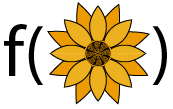

El método de sustitución te permite reemplazar una integral complicada por una más simple. 

** Antes de comenzar: **

Este live script está diseñado para usarse con el código oculto. En la pestaña ** View ** de la barra de herramientas de MATLAB, en la sección ** View **, seleccione ** Hide Code**. Alternativamente, seleccione ** Hide Code ** usando el ícono   en la parte superior derecha del panel Live Editor. 

 Aunque el código está oculto, cierta interactividad requiere familiaridad con MATLAB. Si necesita más instrucción, considere realizar [MATLAB Onramp](https://matlabacademy.mathworks.com/details/matlab-onramp/gettingstarted), un tutorial en línea gratuito de 2 horas que enseña los conceptos básicos de MATLAB.

 Para una experiencia óptima, siga las instrucciones y pasos en la secuencia indicada. Pase a una nueva sección sólo después de completar la anterior. Algunas secciones dependen de variables creadas en secciones anteriores y generarán errores si se agotan. 

clear gPrime uPrime NewMeasure Measure g fa fb fc fu f dxGrp dgGrp ax ax1 ax2 ax3 MyFun MyAnswer LastFive AreaGrpdx
 

##  Inversión de la regla de la cadena para derivadas 

Recuerde que la regla de la cadena para derivadas se parece a 


$$\frac{d}{dx}\left[(f\circ g)(x)\right]=\frac{df}{dg}\cdot \frac{dg}{dx}=f'(g)\cdot g'(x) = f'(g(x))\cdot g'(x)$$


###  Sustitución de integrales indefinidas 

Si aplicamos el concepto de antiderivadas a esta regla, vemos que 


$$f(g(x)) + C = \int \frac{d}{dx}\left[(f\circ g)(x)\right] \; dx =\int f'(g)\cdot g'(x) \; dx$$
     
$$(\Delta)$$


De hecho, porque $dx$ rastrea la medida de un pequeño paso en la dirección de la integración mientras $g'(x)\; dx$ hace lo mismo, podemos definir una nueva medida $dg = g'(x)\; dx$ que nos permite observar que 


$$f(g(x))+C = \int f'(g)\; dg.$$


###  Sustitución de integrales definidas 

Aplicando el teorema fundamental del cálculo, tenemos: 


$$\int_{g(a)}^{g(b)} f'(g) dg = \int_a^b f'(g(x)) \cdot g'(x)\; dx$$


que es 


$$f(g(b))-f(g(a)) = \int_{g(a)}^{g(b)} f'(g) dg = \int_a^b f'(g(x)) \cdot g'(x)\; dx.$$
     
$$(\star)$$


### ** Practica usando la sustitución **

Reescribe cada una de las siguientes integrales en términos de la nueva variable proporcionada por la función de sustitución. Luego resuelve la integral. 

#### ** Ejercicio 1 **

$\displaystyle \int 15\sin(3x^5)x^4\; dx$ donde $g(x) = 3x^5$

Primero, encuentre la derivada de $g(x)$ con respecto a $x$: 

gPrime = @(x) x;

¿Cuál será la nueva medida $dg$ en términos de $x$ y $dx$? 

NewMeasure = @(x,dx)dx;

Si definimos $\displaystyle \int 15\sin(3x^5)x^4\; dx = \int f(g)\; dg$ , ¿qué es $f(g)$ ? 

fa = @(g) g;

Calcula la función $F(x) = \displaystyle \int 15\sin(3x^5)x^4\; dx$. 

Answer = @(x,C) x;
Check1a(gPrime,fa,NewMeasure,Answer);
 

  ** Nota: ** En muchos libros de texto es común usar una variable $u$ en lugar de la variable $g$ en las ecuaciones $(\Delta)$ y $(\star)$ , o incluso llamar a este método $u$ -sustitución. 

#### ** Ejercicio 2 **

$\displaystyle \int_1^3 \left(\frac{1+t}{t^2+5}\right)^{2/3}\left(\frac{5-2t-t^2}{(t^2+5)^2}\right)\; dt$ donde $u(t) = \frac{1+t}{t^2+5}$ 

Calcula la derivada $u'(t)$. 

uPrime = @(t) t;

Calcula los nuevos límites y la nueva medida para la integral en términos de $u$. 

ua = 1;
gb = 3;
NewMeasure = @(t,dt)dt;

Si definimos $\displaystyle \int_1^3 \left(\frac{1+t}{t^2+5}\right)^{2/3}\left(\frac{5-2t-t^2}{(t^2+5)^2}\right)\; dt = \int_{u(a)}^{u(b)} f(u)\cdot du$ , ¿qué es $f(u)$ ? 

f = @(u)u;

Calcula la función $F(t) = \displaystyle \int_1^3 \left(\frac{1+t}{t^2+5}\right)^{2/3}\left(\frac{5-2t-t^2}{(t^2+5)^2}\right)\; dt$. 

try
    Answer =  0;
catch ME
    if contains(ME.message,"Unrecognized function or variable")
        Answer = 0;
        warning("Esta es una integral definida. Tu solución debería ser un número.")
    else
        rethrow(ME)
    end
end
Check1b(uPrime,f,ua,gb,NewMeasure,Answer);
 

#### ** Ejercicio 3 **

$\displaystyle \int e^{r}\cos\left(e^r-17\right)\; dr$ donde $q(r) = e^r-17$ 

Recuerda que $e^x$ se escribe como `exp(x)` en MATLAB. 

gPrime = @(r) r;
NewMeasure = @(r,dr)dr;

Si definimos $\displaystyle \int e^{r}\cos\left(e^r-17\right)\; dr$ $= \int f(q)\cdot \; dq$ , 

fc = @(q) q;
Answer = @(r,C) r;
Check1c(gPrime,fc,NewMeasure,Answer);
 

#### ** Ejercicio 4 **

$\displaystyle \int_{-1}^{2} \left(\ln\left(1+w^2\right)\right)^{7}\left(\frac{w}{1+w^2}\right)\; dw$ donde $g(w) = 1+w^2$. 

gPrime = @(w) w;
ga = -1;
gb = 2;
Measure = @(w,dw)dw;

Recuerde que $\ln(g)$ está escrito `log(g)` en MATLAB. 

Si definimos $\displaystyle \int_{-1}^{2} \left(\ln\left(1+w^2\right)\right)^{7}\left(\frac{w}{1+w^2}\right)\; dw$ $= \displaystyle \int_{g(a)}^{g(b)}f(g)\cdot dg,$

fb = @(g) g;

Este resultado aún no es computable inmediatamente, así que hagamos otra sustitución con $u(g) = \ln(g)$. 

Si definimos $\displaystyle \int_{-1}^{2} \left(\ln\left(1+w^2\right)\right)^{7}\left(\frac{w}{1+w^2}\right)\; dw$ $= \displaystyle \int_{u(a)}^{u(b)}f(u)\cdot du,$

ua = -1;
ub = 2;

Calculando $du$ como una función de $g$ : 

NewMeasure = @(g,dg)dg;
fu = @(u) u;

Poniendo todo junto, calculamos el resultado: 

try
    Answer =  0;
catch ME
    if contains(ME.message,"Unrecognized function or variable")
        Answer = 0;
        warning("Esta es una integral definida. Tu solución debería ser un número.")
    else
        rethrow(ME)
    end
end
Check1d(gPrime,fb,ga,gb,Measure,NewMeasure,ua,ub,fu,Answer);
 

##  Visualizando variables cambiantes 

clear x
syms x %#ok<NASGU>

Puede ser contradictorio visualizar cómo un cambio de variables afecta su función o la integral resultante. Utilice esto para investigar diferentes combinaciones de funciones. 

###  Un paso a la vez 

 Configura las funciones a usar: 

f = @(x)sin(x);
g = @(x)log(x+5.001);

Elige un punto final izquierdo $a$ y un punto final derecho $b$ tal que $a \leq x \leq b$ : 

a =-3.4; b = 2.1;
if a > b
    warning("Este código asume que a<b. Por favor, ajusta tus valores en consecuencia.")
end
tVals = linspace(min(a,b),max(a,b),10000);
gVals = double(g(tVals));
fVals = double(f(gVals));

Visualiza el gráfico como $f(g(x))$ vs $x$ o $f(g(x))$ vs $g(x)$ : 

displayXvsF = 1;
clear p2
figure

[ax,p1,yM,ym] = CreateBasePlot(tVals,gVals,fVals,displayXvsF);
 

  ** Pruebe **. 

- $f(x) = \sin(x)$ y $g(x) = \ln(x+0.001)$ con $a=0$ y $b = 2.1$ ? 

- $f(x) = \sin(x)$ y $g(x) = \ln(x+0.001)$ con $a=1$ y $b = 1.1$ ? o con $a=0$ y $b = 0.1$ ? 

- $f(x) = \cos(x)$ y $g(x) = e^x$ con $a = 0$ y $b=0.1$ ? o $a=2$ y $b = 2.1$? o $a = 2$ y $b=5$? 

- $f(x) = \cos(x)$ y $g(x) = e^x$ con $a = 5$ y $b = 5$ ? 

- ¡Cualquier otra función que te guste! 

Elija un tamaño de paso y un punto inicial: 

Step = 0.75; x0 = 1.1;
 
Flag = "xdx";

if ~exist("p1","var")
    if ~exist("displayXvsF","var")
        disp("Assuming default values:")
        f = @(x)sin(x);
        g = @(x)log(x+5.001);
        tVals = linspace(-3.4,2.1,10000);
        gVals = double(g(tVals));
        fVals = double(f(gVals));
        [ax,p1,yM,ym] = CreateBasePlot(tVals,gVals,fVals,1);
    else
        [ax,p1,yM,ym] = CreateBasePlot(tVals,gVals,fVals,displayXvsF);
    end
end

y0 = double(f(g(x0)));
y1 = double(f(g(x0+Step)));
g0 = double(g(x0));
g1 = g0+Step;
g2 = double(g(x0+Step));

switch Flag
    case "gdx"
        disp("El tamaño del paso mostrado es dg = "+Step+" y el punto inicial es g_0="+g0+".")
        if (g0+Step > max(gVals)) || (g0+Step < min(gVals))
            warning("Este tamaño de paso se mueve fuera de la ventana del dominio mostrada.")
        end
        title(ax,"Mostrando el efecto del tama\~no de paso elegido $dg =$"+Step,"Interpreter","latex")
        p1.XData = gVals;
        ax.XLim = [min(gVals) max(gVals)];
        xlabel(ax,"$g(x)$","Interpreter","latex")
        if exist("p2","var")
            p2(1).XData = [g0 g0];
            p2(2).XData = [g1 g1];
            ax.Legend.String = ["$g(x_0)$" "$g(x_0)+dg$"];
        else
            hold on
            yM = max(fVals);
            ym = min(fVals);
            p2 = plot(ax,[g0 g0],[ym yM],[g1 g1],[ym yM]);
            hold off
            legend(["" "$g(x_0)$" "$g(x_0)+dg$"],Interpreter="latex",Location="northwest")
        end
    case "xdx"
        disp("El tamaño del paso mostrado es dx = "+Step+" y el punto inicial es x_0="+x0+".") %#ok<*UNRCH>
        if (x0+Step > max(tVals)) || (x0+Step < min(tVals))
            warning("Este tamaño de paso se mueve fuera de la ventana del dominio mostrada.")
        end
        p1.XData = tVals;
        ax.XLim = [tVals(1) tVals(end)];
        t0 = x0;
        t1 = x0+Step;
        y1 = double(f(g(x0+Step)));
        xlabel(ax,"$x$","Interpreter","latex")
        title(ax,"Mostrando el efecto de un tama\~no de paso constante $dx = $"+Step,"Interpreter","latex")
        if exist("p2","var")
            p2(1).XData = [t0 t0];
            p2(2).XData = [t1 t1];
            ax.Legend.String = ["$x_0$" "$x_0+dx$"];
        else
            hold on
            p2 = plot(ax,[t0 t0],[ym yM],[t1 t1],[ym yM]);
            hold off
            legend(["" "$x_0$" "$x_0+dx$"],Interpreter="latex",Location="northwest")
        end
    case "gdg"
        disp("El tamaño del paso es dx ="+Step+".")
        disp("Por lo tanto, el tamaño del paso mostrado es dg = "+(g2-g0)+" y el punto inicial es g_0="+g0+".")
        if ~isreal(g2)
            warning("Este valor está fuera del dominio real de g. Por favor, elige un tamaño de paso diferente.")
        else
            if (g2 > max(gVals)) || (g2 < min(gVals))
                warning("Este tamaño de paso se mueve fuera de la ventana del dominio mostrada.")
            end
            title(ax,"Mostrando el efecto de la sustituci\'on en el tamaño del paso $dg = g(x_0+dx)-g(x_0)$","Interpreter","latex")
            p1.XData = gVals;
            ax.XLim = [min(gVals) max(gVals)];
            xlabel(ax,"$g(x)$","Interpreter","latex")
            if exist("p2","var")
                p2(1).XData = [g0 g0];
                p2(2).XData = [g2 g2];
                ax.Legend.String = ["$g(x_0)$" "$g(x_0+dx)$"];
            else
                hold on
                p2 = plot(ax,[g0 g0],[ym yM],[g2 g2],[ym yM]);
                hold off
                legend(["" "$g(x_0)$" "$g(x_0+dx)$"],Interpreter="latex",Location="northwest")
            end
        end
end

Observe el hecho de que la distancia real recorrida por un "tamaño de paso" dado puede cambiar bastante dependiendo de la elección del punto inicial $x_0$ así como de la elección a considerar un $dg$ fijo, o un $dx$ fijo o un $dg = g(x_0+dx)-g(x_0)$ calculado. 

  ** Pruebe **. 

- Mueva los valores en $x_0$ control deslizante completamente hacia la derecha con $dx = -0.05$ y $y$and$g(x) = \ln(x+5.001)$and$b=5$. ¿Lo que sucede? 

- Mueva los valores en $x_0$ control deslizante completamente hacia la izquierda con $dx = 0.05$ y $f(x) = \sin(x)$and$g(x) = \ln(x+5.001)$and$a=-5$. ¿Qué sucede? 

- Mueva los valores en $dx$ control deslizante completamente hacia la izquierda y hacia la derecha con un valor constante de $x_0$. ¿Lo que sucede? 

- Cambie el desplegable para ver un gráfico de $f(x)$ frente a $g(x)$ y repita los pasos 1-4. ¿Lo que sucede? 

- Intente cambiar las funciones $Rampa de entrada de MATLAB$and$g(x)$ , por ejemplo a `cos(x)` y `exp(x).` Si los límites de sus controles deslizantes no tienen sentido para las nuevas funciones, puede establecer valores directamente editando el campo numérico o puede hacer clic derecho en el controles deslizantes y establezca nuevos valores mínimos y máximos. 

###  Visualice las subdivisiones en áreas enteras 

Configure las funciones y los límites a utilizar. 

clear f g p3
syms x
f(x) = sin(x); % pecado(x)
g(x) = 1/(1+x^2); % 1/(1+x^2) funciona bien, solía usar x^4
 
a =-1.2; b = 6.9;
NumIntervals = 59;
tVals = linspace(min(a,b),max(a,b),ceil(1000/NumIntervals)*NumIntervals);
gVals = double(g(tVals));
fVals = double(f(gVals));
p3 = plot(gVals,fVals);
ax3 = p3.Parent;
title(ax3,"Mostrar el \'area con signo entre $f(g(x))$ y el eje $g(x)$","Interpreter","latex")
hold on
xlabel(ax3,"$g(x)$",Interpreter="latex")
ylabel(ax3,"$f(g(x))$",Interpreter="latex")
ShowPosNegArea(ax3,fVals,gVals);

####  Animar la visualización mediante pasos de tamaño original o de sustitución 

Primero, muestre las posiciones de los intervalos definidos por un tamaño de paso constante $dg$, luego subdivida la misma región por intervalos definidos por un tamaño de paso constante $dx$ debajo del mapa $g(x_k+dx) = g(a+kdx)$ donde $x_k$ es el punto inicial del intervalo $k^{\text{th}}$. De manera equivalente, $x = a$ es el límite inferior del intervalo correspondiente. 

NumIntervals =73;
tVals = linspace(min(a,b),max(a,b),ceil(1000/NumIntervals)*NumIntervals);
StepSize = ceil(1000/NumIntervals);
gVals = double(g(tVals));
fVals = double(f(gVals));
idx = 1:StepSize:length(tVals);
ConstdgDomain = linspace(gVals(1),gVals(end),length(idx));
ConstfVals = double(f(ConstdgDomain));
RunAnimateStripes = true;     
MaxContrast = round(1-ax3.Parent.Color);
if RunAnimateStripes
    delete(ax3.Children(1:end-2))
    dxGrp = hggroup;
    dgGrp = hggroup;
    subtitle("Con constante $dg$","Interpreter","latex")
    dgGrp = AnimateStripes(ax3,ConstdgDomain,ConstfVals,1:length(idx),dgGrp,ContrastColor=MaxContrast);
    dgGrp = AddStartEnd(ax3,ConstdgDomain,dgGrp);
    dgGrp.Visible = "off";
    subtitle("Con constante $dx$","Interpreter","latex")
    dxGrp = AnimateStripes(ax3,gVals,fVals,idx,dxGrp,ContrastColor=MaxContrast);
    dxGrp = AddStartEnd(ax3,gVals,dxGrp);
    hold off
else
    dxGrp = hggroup;
    dgGrp = hggroup;
    dgGrp = AnimateStripes(ax3,ConstdgDomain,ConstfVals,1:length(idx),dgGrp,flag=0,ContrastColor=MaxContrast);
    dgGrp.Visible = "off";
    subtitle("Mostrando constante $dx$","Interpreter","latex")
    dxGrp = AnimateStripes(ax3,gVals,fVals,idx,dxGrp,flag=0,ContrastColor=MaxContrast);
    hold off
end
SetXTicks(ax3,[gVals(1) gVals(end)],["g(a)" "g(b)"])

####  Mostrar solo un conjunto de pasos 

Si la casilla de verificación está seleccionada, el gráfico muestra la región subdividida en intervalos de tamaño constante $dg$. Si la casilla de verificación no está seleccionada, el gráfico muestra la región subdividida en intervalos de tamaño constante $dx$. En el último caso, los extremos del intervalo trazado ocurren después de las longitudes $dg = g'(x)dx$. Debido a que esto depende del valor de $g'(x)$, puede ser una transformación lineal, pero también puede ser altamente no lineal. 

  ** Pruebe **. 

- ¿Qué sucede cuando $g(x)$ es una función lineal? 

- ¿Qué sucede cuando $g'(x)$ es periódico? 

- ¿Qué sucede cuando $g'(x)$ adopta una amplia gama de valores en un dominio determinado? 

Flag = true;     
if Flag
    dgGrp.Visible = "on";
    dxGrp.Visible = "off";
    subtitle("Mostrando constante $dg$ steps","Interpreter","latex")
else
    dgGrp.Visible = "off";
    dxGrp.Visible = "on";
    subtitle("Mostrando constante $dx$ steps","Interpreter","latex")
end

##  Visualización completa del proceso de sustitución 

Configure las funciones y los límites a utilizar. 

clear f g p3
syms x f(x) g(x)
f(x) = sin(x); % pecado(x)
g(x) = x^2; % 1/(1+x^2) funciona bien, solía usar x^4
 
a =-1.2; b = 1.7;
NumIntervals = 1000;
[tVals,uVals,fOfuVals,fVals,gPrime] = ComputeTUFGVals(a,b,@(x)g(x),@(x)f(x),NumIntervals);
tl = tiledlayout(1,2);
tl.Parent.Position = [680 458 800 420];
ax1 = nexttile(tl,[1 1]);
plot(ax1,tVals,fVals);
ax1.XLim = sort([a b]);
% ax11 = tl11.Padre;
area11 = double(int(f(g(x))*gPrime(x),x,a,b));
title("Mostrar el \'area con signo bajo $f(g(x))*g'(x)$","Interpreter","latex")
subtitle("Area = "+area11)
xlabel("$x$","Interpreter","latex")
ylabel("$f(g(x))g'(x)$","Interpreter","latex")
ShowPosNegArea(ax1,fVals,tVals,pnFlag=true);
ax2 = nexttile;
plot(ax2,uVals,fOfuVals);
ax2.XLim = double([min(uVals) max(uVals)]);
xlabel("$g(x)$",Interpreter="latex")
ylabel("$f(g(x))$",Interpreter="latex")
ShowPosNegArea(ax2,double(fOfuVals),double(uVals),pnFlag=true);
area12 = int(f(x),x,double(g(a)),double(g(b)));
title("\'Area bajo $f(g)$ como funci\'on de $g$","Interpreter","latex")
subtitle("Area = "+double(area12))

####  Animar la visualización mediante pasos de tamaño original o de sustitución 

Primero, muestre las posiciones de los intervalos definidos por un tamaño de paso constante $dg$, luego subdivida la misma región por intervalos definidos por un tamaño de paso constante $dx$ debajo del mapa $g(x_k+dx) = g(a+kdx)$ donde $x_k$ es el punto inicial del intervalo $k^{\text{th}}$. De manera equivalente, $x = a$ es el límite inferior del intervalo correspondiente. 

¿Cuántos intervalos? 

NumIntervals =73;
[tVals,uVals,fOfuVals,fVals,gPrime] = ComputeTUFGVals(a,b,@(x)g(x),@(x)f(x),NumIntervals);
idx = 1:StepSize:length(tVals);
ConstdgDomain = linspace(gVals(1),gVals(end),length(idx));
ConstfVals = double(f(ConstdgDomain));
minGVals = double(min(gVals));
minGtVals = double(min(g(tVals(idx))));
maxGVals = double(max(gVals));
maxGtVals = double(max(g(tVals(idx))));
BestLims = [min(minGVals,minGtVals) max(maxGVals,maxGtVals)];
clf
ax2 = axes;
ax2.XLim = BestLims;
RunAnimateStripes = true;  
AreaGrpdx = ShowPosNegArea(ax2,double(f(g(tVals(idx)))),double(g(tVals(idx))));
if RunAnimateStripes
    MaxContrast = round(1-ax2.Parent.Color);
    delete(ax2.Children(2:end-1))
    dxGrp = hggroup;
    dgGrp = hggroup;
    subtitle("Con constante $dg$","Interpreter","latex")
    dgGrp = AnimateStripes(ax2,ConstdgDomain,ConstfVals,1:length(idx),dgGrp,ContrastColor=MaxContrast);
    dgGrp = AddStartEnd(ax2,ConstdgDomain,dgGrp);
    dgGrp.Visible = "off";
    subtitle("Con constante $dx$","Interpreter","latex")
    dxGrp = AnimateStripes(ax2,double(g(tVals(idx))),double(f(g(tVals(idx)))),1:length(idx),dxGrp,ContrastColor=MaxContrast);
    dxGrp = AddStartEnd(ax2,gVals,dxGrp);
    hold off
else
    dxGrp = hggroup;
    dgGrp = hggroup;
    AreaGrpdg = ShowPosNegArea(ax2,double(fOfuVals),double(uVals));
    dgGrp = AnimateStripes(ax2,ConstdgDomain,ConstfVals,1:length(idx),dgGrp,flag=0,ContrastColor=MaxContrast);
    dgGrp.Visible = "off";
    AreaGrpdg.Visible = "off";
    subtitle("Mostrando constante $dx$","Interpreter","latex")
    dxGrp = AnimateStripes(ax2,double(g(tVals(idx))),double(f(g(tVals(idx)))),1:length(idx),dxGrp,flag=0,ContrastColor=MaxContrast);
    hold off
end
SetXTicks(ax2,[gVals(1) gVals(end)],["g(a)" "g(b)"])

#### Mostrar solo un conjunto de pasos 

Si la casilla de verificación está seleccionada, el gráfico muestra la región subdividida en intervalos de tamaño constante $dg$. Si la casilla de verificación no está seleccionada, el gráfico muestra la región subdividida en intervalos de tamaño constante $dx$. En el último caso, los extremos del intervalo trazado ocurren después de las longitudes $dg = g'(x)dx$. Debido a que esto depende del valor de $g'(x)$, puede ser una transformación lineal, pero también puede ser altamente no lineal. 

  ** Pruebe **. 

- ¿Qué sucede cuando $g(x)$ es una función lineal? 

- ¿Qué sucede cuando $g'(x)$ es periódico? 

- ¿Qué sucede cuando $g'(x)$ adopta una amplia gama de valores en un dominio determinado? 

Flag = false;    
if Flag
    dgGrp.Visible = "on";
    dxGrp.Visible = "off";
    subtitle("Mostrando constante $dg$ steps","Interpreter","latex")
else
    dgGrp.Visible = "off";
    dxGrp.Visible = "on";
    subtitle("Mostrando constante $dx$ steps","Interpreter","latex")
end

##  Practique integrales de sustitución aleatoria 

  ** Pro-tip **. La sintaxis de MATLAB es 7 `*t^(2/3)` para $7t^{2/3}$. La variable que uses en la solución es importante, al igual que el uso apropiado de paréntesis y operadores de multiplicación. 

% Borrar variables que pueden reutilizarse en otras partes de este módulo.
clear ErrorCount TotSubProbs TotAttempts adjustcount LastFive MyFun VarChoice
syms t r x z C              % Declarar variables simbólicas
VarOpts = [t r x z];        % Definir la lista de variables a utilizar en los problemas.
ErrorCount = 0;             % Inicializar un recuento de errores
TotSubProbs = 0;            % Inicializar un recuento del total de problemas intentados
TotAttempts = 0;            % Inicializar un recuento del total de soluciones ofrecidas
AdjustCount = 0;            % Conservar los recuentos si el usuario vuelve a enviar una solución
LastFive = zeros(1,5);      % Inicializar una matriz para registrar los últimos cinco resultados de la solución
 
disp("Valores inicializados para la práctica de Sustitución.")

% Compruebe si la sección anterior se ha ejecutado
% Si no, proporcione una advertencia. Si es así genera un problema.
if ~exist("TotSubProbs","var")
    warning("Debes inicializar los valores antes de poder generar un problema.")
else
    [MyFun,VarChoice] = GenProbType(VarOpts,1);  % genProbType está definido en Funciones auxiliares
    % genProbType configura una variable y genera una función aleatoria
    TotSubProbs = TotSubProbs+1;     % Aumentar el recuento total de problemas intentados.
end
                                    % Run this section

MyAnswer = r;     % Solución definida por el usuario, valor predeterminado r
TotAttempts = TotAttempts + 1;       % Recuento de actualizaciones del total de intentos de solución
[LastFive,ErrorCount,TotAttempts,AdjustCount] = ResubmissionCheck(TotAttempts,TotSubProbs, ...
    AdjustCount,MyFun,VarChoice,MyAnswer,ErrorCount,LastFive);
% ResubmissionCheck is defined in Local Helper Functions
% ResubmissionCheck records the attempt and provides appropriate feedback
Check1(MyFun,VarChoice,MyAnswer,ErrorCount,LastFive);
                          % Run this section

Una vez que haya completado suficiente práctica, realice un seguimiento de los resultados generales de su práctica aquí: 

 
AnalyzeResults(TotSubProbs,ErrorCount,TotAttempts,AdjustCount,LastFive)

### Aplicación de práctica 

Puede practicar en la aplicación Calculus Flashcards. Puede iniciar la aplicación haciendo clic en la imagen a continuación. Debes configurar el tipo de problema como "Sustitución" en la sección Integrales. La aplicación se abrirá en una nueva ventana. 

[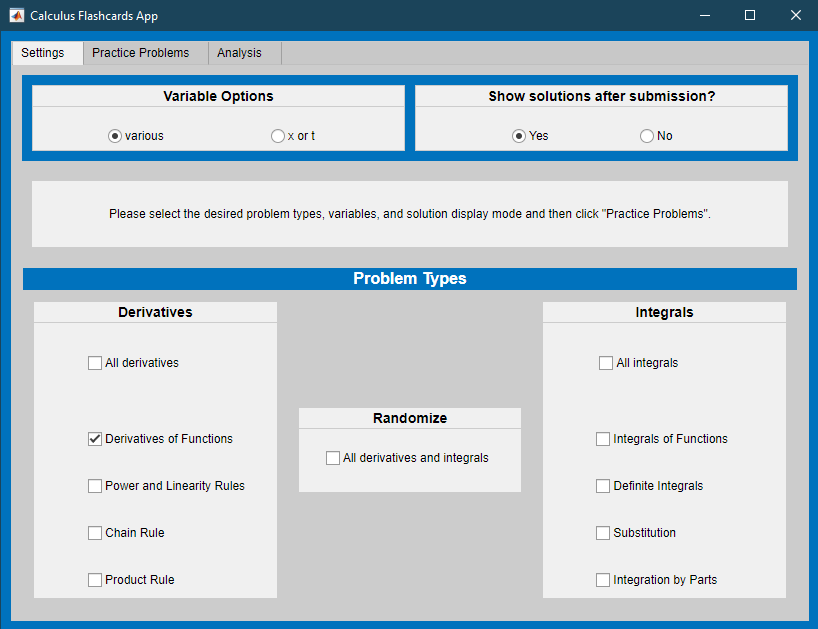](matlab: CalculusFlashcards)

[Aplicación Tarjetas didácticas de cálculo](matlab: TarjetasDeCalculo)

 
TarjetasDeCalculo

[⇦ Menú principal](matlab:open('MainMenu.mlx'))

##  Funciones auxiliares locales 

Si desea ver los detalles del código, seleccione la pestaña** View **y cambie a **Output inline**. Como alternativa, seleccione **Output inline** usando el ícono   en la parte superior derecha del panel Live Editor. 

function [tVals,uVals,fOfuVals,fVals,gPrime] = ComputeTUFGVals(a,b,g,f,NumIntervals)
syms x
gPrime(x) = diff(g(x),x);
fgp(x) = f(g(x))*gPrime(x);
tVals = linspace(a,b,ceil(1000/NumIntervals)*NumIntervals+1);
uVals = linspace(g(a),g(b),NumIntervals+1);
fOfuVals = double(f(uVals));
fVals = double(fgp(tVals));
end

function [ax,p1,yM,ym] = CreateBasePlot(tVals,gVals,fVals,displayXvsF)
p1 = plot(gVals,fVals);
ax = p1.Parent;
ylabel(ax,"$f(g(x))$","Interpreter","latex")

if displayXvsF
    p1.XData = tVals;
    ax.XLim = [tVals(1) tVals(end)];
    title(ax,"Trazado de $f(x)$ contra $x$","Interpreter","latex")
    xlabel(ax,"$x$","Interpreter","latex")
else
    p1.XData = gVals;
    ax.XLim = [min(gVals) max(gVals)];
    title(ax,"Trazado de $f(x)$ contra $g(x)$","Interpreter","latex")
    xlabel(ax,"$g(x)$","Interpreter","latex")
end

yM = ax.YLim(2);
ym = ax.YLim(1);
end

function [posRegs,negRegs,allOrderedRegs] = FindSignSwitchIndexes(fVals,dVals,f0)
% fVals es un vector de dobles que se compara con una constante
% f0 en puntos dados por dVals, un vector de dobles del mismo tamaño.
%  Cada región no negativa/no positiva es una fila en posRegs/negRegs,
%  respectivamente La primera y la última columna son indicadores
% (1/0) que indican (sí/no) la necesidad de interpolación al principio/final
% de la región La segunda columna es el índice en fVals/dVals del
% primer par en esa región La tercera columna es el índice en fVals/dVals
% del último par en esa región Si no hay pares fVals/dVals en la
% región, la segunda y tercera columnas contendrán NaN allOrderedRegs
% combina posRegs y negRegs con una quinta columna que *--- * rastrea
% el signo (1 para positivo, -1 para negativo) en el orden en que
% ocurren moviéndose a través de dVals

ddVals = dVals(2:end)-dVals(1:end-1);

posDU = ddVals > 0;
zeroDU = ddVals == 0;
negDU = ones(size(ddVals))-posDU-zeroDU;

posF = fVals>=f0;
negF = fVals<=f0;

posPosVals = (posDU + posF(1:end-1) + posF(2:end))==3;
negNegVals = (negDU + negF(1:end-1) + negF(2:end))==3;
allPosVals = posPosVals + negNegVals;
startPosRegIdx = find((allPosVals - [0 allPosVals(1:end-1)])==1);
endPosRegIdx = find(([allPosVals(2:end) 0] - allPosVals)==-1);
if size(startPosRegIdx) ~= size(endPosRegIdx)
    ME = MException("IndexFinder:PairFailure","Regiones de inicio/fin no coincidentes");
    throw(ME)
end
posRegs = zeros([length(startPosRegIdx),4]);
posRegs(:,2) = startPosRegIdx';
posRegs(:,3) = endPosRegIdx';

posNegVals = (posDU + negF(1:end-1) + negF(2:end))==3;
negPosVals = (negDU + posF(1:end-1) + posF(2:end))==3;
allNegVals = posNegVals + negPosVals;
startNegRegIdx = find((allNegVals - [0 allNegVals(1:end-1)])==1);
endNegRegIdx = find(([allNegVals(2:end) 0] - allNegVals)==-1);
if size(startNegRegIdx) ~= size(endNegRegIdx)
    ME = MException("IndexFinder:PairFailure","Regiones de inicio/fin no coincidentes");
    throw(ME)
end
negRegs = zeros([length(startNegRegIdx),4]);
negRegs(:,2) = startNegRegIdx';
negRegs(:,3) = endNegRegIdx';

allZeroVals = zeroDU;

regIdentified = allPosVals + allNegVals + allZeroVals;

interpIdx = find(regIdentified == 0);
for k = 1:length(interpIdx)
    if ismember(interpIdx(k)+1,startPosRegIdx)
        idx = startPosRegIdx==(interpIdx(k)+1);
        posRegs(idx,1) = 1;
    elseif ismember(interpIdx(k)+1,startNegRegIdx)
        idx = startNegRegIdx==(interpIdx(k)+1);
        negRegs(idx,1) = 1;
    elseif (posDU(interpIdx(k)) && posF(interpIdx(k)+1))||(negDU(interpIdx(k)) && negF(interpIdx(k)+1))
        posRegs = [posRegs;1 nan nan 1]; %#ok<AGROW>
    elseif (negDU(interpIdx(k)) && posF(interpIdx(k)+1))||(posDU(interpIdx(k)) && negF(interpIdx(k)+1))
        negRegs = [negRegs;1 nan nan 1]; %#ok<AGROW>
    else
        warning("Valor de índice no coincidente marcado para interpolación.")
    end
    if ismember((interpIdx(k)-1),endPosRegIdx)
        idx = endPosRegIdx==(interpIdx(k)-1);
        posRegs(idx,4) = 1;
    elseif ismember((interpIdx(k)-1),endNegRegIdx)
        idx = endNegRegIdx==(interpIdx(k)-1);
        negRegs(idx,4) = 1;
    end
end

[numPosRegs,~] = size(posRegs);
[numNegRegs,~] = size(negRegs);

allRegs = [posRegs ones([numPosRegs 1]);...
    negRegs -1*ones([numNegRegs 1])];
allOrderedRegs = sortrows(allRegs,2);
end


function xz = FindInterpVal(xl,xr,fl,fr,f0)
% FindInterpVals toma las coordenadas de dos puntos (xl,fl) y (xr,fr) y un
% valor intermedio f0 entre fl y fr y devuelve la coordenada xz
% estimando dónde la línea entre ellos cruza el valor y = f0
if (fr-f0)*(fl-f0)>=0
    ME = MException("InterpVal:IntervalError","f0 ("+f0+") no está entre fl ("+fl+") y fr ("+fr+")");
    throw(ME)
end
%% Calcular la pendiente entre (xl,fl) y (xr,fr)
mf = (fr-fl)/(xr-xl);
%% Resolviendo la aproximación lineal f0 = mf*(xz-xl)+fl para xz
xz = (f0-fl)/mf+xl;

end

function varargout = ShowPosNegArea(ax,fVals,dVals,opts)
arguments
    ax
    fVals
    dVals
    opts.f0 = 0
    opts.overlapsFlag = 2
    opts.pnFlag = 0
end
%trama(ax,dVals,fVals,"k")
hold on
[posRegs,negRegs,allRegs] = FindSignSwitchIndexes(fVals,dVals,opts.f0);
cols = ["b" "r"];

[numPosRegs,~] = size(posRegs);
[numNegRegs,~] = size(negRegs);
[numRegs,~] = size(allRegs);

if opts.overlapsFlag == 1
    alphaVal = 1/ceil(numRegs/2);
elseif opts.overlapsFlag == 2
    alphaVal = .5;
else
    alphaVal = 1;
end

if opts.pnFlag
    posGrp = DrawColoredPolys(ax,fVals,dVals,posRegs,numPosRegs,cols(1),opts.f0,alphaVal);
    negGrp = DrawColoredPolys(ax,fVals,dVals,negRegs,numNegRegs,cols(2),opts.f0,alphaVal);
    varargout{1} = posGrp;
    varargout{2} = negGrp;
else
    allGrp = DrawColoredPolys(ax,fVals,dVals,allRegs,numRegs,cols(1),opts.f0,alphaVal);
    varargout{1} = allGrp;
end

hold off
end

function polyGrp = DrawColoredPolys(ax,fVals,dVals,Regs,numRegs,col,f0,alphaVal)
polyGrp = hggroup;
for k = 1:numRegs
    xVals = dVals(Regs(k,2):Regs(k,3)+1);
    yVals = fVals(Regs(k,2):Regs(k,3)+1);
    if Regs(k,1)
        xnew = FindInterpVal(dVals(Regs(k,2)-1),xVals(1),...
            fVals(Regs(k,2)-1),yVals(1),f0);
        xVals = [xnew xVals]; %#ok<AGROW>
        yVals = [f0 yVals]; %#ok<AGROW>
    end
    if Regs(k,4)
        xnew = FindInterpVal(xVals(end),dVals(Regs(k,3)+2),...
            yVals(end),fVals(Regs(k,3)+2),f0);
        xVals = [xVals xnew]; %#ok<AGROW>
        yVals = [yVals f0]; %#ok<AGROW>
    end
    x = [xVals flip(xVals)];
    y = [f0*ones(size(yVals)) flip(yVals)];
    patch(ax,x,y,col,"FaceAlpha",alphaVal,"Parent",polyGrp);
    pause(.1)
end
end

function lineGroup = AddStartEnd(ax,x,lineGroup)
plot(ax,[x(end) x(end)],ax.YLim,"r-","LineWidth",2,"Parent",lineGroup);
plot(ax,[x(1) x(1)],ax.YLim,"c-","LineWidth",2,"Parent",lineGroup);
end

function lineGroup = AnimateStripes(ax,x,y,idx,lineGroup,opts)
arguments
    ax
    x
    y
    idx
    lineGroup
    opts.flag = true
    opts.ContrastColor = [0 0 0]
end
% x e y tienen la misma longitud, por lo que esto simplemente crea y agrega a
% la colección lineGroup relevante de líneas trazadas en los valores de índice
% dados por idx
% si la bandera está configurada , mostrar como animación
if length(idx)>1
    p = plot(ax,[x(idx(1)) x(idx(1))],[0 y(idx(1))],"Parent",lineGroup,Color=opts.ContrastColor);
    for k = 2:length(idx)
        copyobj(p,lineGroup)
        if x(idx(k))>= x(idx(k-1))
            lineGroup.Children(k).Color = opts.ContrastColor;
            lineGroup.Children(k).LineWidth = 1;
        else
            lineGroup.Children(k).Color = "y";
            lineGroup.Children(k).LineWidth = 1;
        end
        lineGroup.Children(k).XData = [x(idx(k)) x(idx(k))];
        lineGroup.Children(k).YData = [0 y(idx(k))];
        if opts.flag
            drawnow
        end
    end
end
lineGroup = AddStartEnd(ax,x,lineGroup);
end

function SetXTicks(ax,newVals,newNames)
XTickSpacing = .75*(ax.XTick(2)-ax.XTick(1));
remXVals = ax.XTick((abs(ax.XTick - newVals(1)) > XTickSpacing) & (abs(ax.XTick - newVals(2)) > XTickSpacing));
starXN = string(cell2mat(pad(ax.XTickLabel)));
remXN = starXN((abs(ax.XTick - newVals(1)) > XTickSpacing) & (abs(ax.XTick - newVals(2)) > XTickSpacing));
if newVals(1)==newVals(2)
    newLabel = newNames(1) + " = " + newNames(2);
    newVals = newVals(1);
else
    newLabel = newNames;
end
[xV,idx] = sort([newVals remXVals]);
allNames = [newLabel remXN'];
xN = allNames(idx);
xticks(ax,xV);
xticklabels(ax,xN);
end

% % Práctica de funciones generadoras de problemas

function AnalyzeResults(totProbs,errorCount,totAttempts,adjustCount,lastFive)
% AnalyzeResults proporciona retroalimentación en el caso de un solo tipo de problema
% totProbs, errorCount, totAttempts y ajustaCount son números enteros
% lastFive es un vector
overallRight = (1 - sum(errorCount)/sum(totProbs))*100;
if sum(totAttempts) > sum(totProbs)
    % Si el usuario ha vuelto a enviar después de ver la solución, responda
    disp("¿Por qué estás reenviando después de saber la solución?")
    disp("Los reenvíos no se incluyen en tus estadísticas.")
    if sum(adjustCount) > 1
        % Si el usuario está reenviando repetidamente, anímalo a usar
        % este generador de problemas como se pretende, comenzando de nuevo
        disp("Has reenviado " + sum(adjustCount) + " veces.")
        disp("Por favor, considera reiniciar el conteo usando el botón `Inicializar Valores'.")
    end
end
if totProbs >= 5
    lastCorrect = sum(lastFive);
    % If more than 5 problems have been attempted, provide grammatically
    % appropriate feedback on success rates
    if lastCorrect > 1
        str = compose("La tasa de éxito general es %.1f%% en %i problemas totales \n\n" + ...
            "De los últimos cinco, %i fueron correctos.",overallRight,totProbs,lastCorrect);
    elseif lastCorrect == 1
        str = compose("La tasa de éxito general es %.1f%% en %i problemas totales \n\n" + ...
            "De los últimos cinco, uno fue correcto.",overallRight,totProbs);
    elseif lastCorrect == 0
        str = compose("La tasa de éxito general es %.1f%% en %i problemas totales \n\n" + ...
            "De los últimos cinco, ninguno fue correcto.",overallRight,totProbs);
    end
else
    % Si se han intentado menos de 5 problemas, fomente la perseverancia.
    str = compose("La tasa de éxito general es %.1f%% en %i problemas totales \n\n" + ...
        "Por favor, haz al menos cinco problemas.",overallRight,totProbs);
end
disp(str)
end

function [lastFive,errorCount] = Check1(myFunc,myVar,myAnswer,errorCount,lastFive)
% Check1 genera respuestas correctas al diferenciar y actualizar
% errorCount y lastFive
%
% Entradas: myFunc es la función simbólica para diferenciar
% o integrar myVar es la variable independiente myAnswer es
% la función o número de prueba simbólico errorCount es un número
% entero que rastrea el total de intentos incorrectos *-- -*
% lastFive es un vector que rastrea los últimos cinco intentos
% Salida: correctAnswer es una función simbólica que es la solución
% a probType aplicada a myFunc(myVar) con bds
syms C
correctAnswer = int(myFunc,myVar)+C;
lastFive(1:4) = lastFive(2:5);
disp("Cuando se simplifica, esta función es: ")
disp(myAnswer)
if correctAnswer == myAnswer
    disp("Esa respuesta es correcta.")
    lastFive(5) = 1;
elseif isAlways(diff(myAnswer,myVar)-myFunc==0,"Unknown","false")
    if diff(myAnswer,C) == 1
        disp("Esa respuesta es correcta. Otra forma posible es:")
        disp(correctAnswer-C + "C")
        lastFive(5) = 1;
    else
        disp("Te falta un +C.")
        disp("La respuesta correcta es:")
        correctAnswer %#ok<NOPRT>
        errorCount = errorCount + 1;
        lastFive(5) = 0;
    end
else
    disp("Eso es incorrecto. La respuesta correcta es:")
    correctAnswer %#ok<NOPRT>
    errorCount = errorCount + 1;
    disp("Por favor, inténtalo de nuevo con un nuevo problema.")
    lastFive(5) = 0;
end
end

function [myFun,varChoice] = GenProbType(varOpts,probType)
% genProbType configura una variable y genera una función aleatoria
%
% Entradas: varOpts es una matriz de posibles variables
% probType es una cadena que identifica el tipo de función
% Salidas: myFun es una función simbólica
% varChoice es la variable independiente
% probType es un número entero que rastrea el tipo de pregunta formulada
% [a, b] son los límites de la integral definida, si es necesario

% Seleccione aleatoriamente una variable del conjunto varOpts
varChoice = varOpts(randi([1 length(varOpts)],1));

% Utilice genFunDiff para generar funciones simples
% genFunDiff se define en Funciones auxiliares
% Las entradas a genFunDiff son la variable varChoice, un rango de valores
% entre los cuales seleccionar coeficientes y un valor que indica cuál Las advertencias
% ya se han impreso durante la generación del problema.
switch probType
    case 1 % derivada simple
        syms f(x) g(x) x
        [f(x),prevFuncType] = GenFunDiff([1 3],x,[1 10],0);
        g(x) = GenFunDiff([1 5],x,[5 10],prevFuncType);
        myFun = diff(f(g(varChoice)),varChoice);
        % Mostrar el problema integral
        disp("Calcula la integral:")
        displayFormula("F(varChoice) == int(myFun,varChoice)")
end
end

function [myFunc,type] = GenFunDiff(bds,var,range,prevFuncType)
syms f(t)                    % Crear una función simbólica f(t)
params = randi(bds,[1 4]);   % Elija aleatoriamente los valores de los parámetros
shift = randi([0 max(abs(bds))],1); % Elija aleatoriamente un turno que puede ser 0
sgns = randi([0 1],[1 3]);   % Elija aleatoriamente signos +/-
type = randi(range,1);


% Para facilitar la lectura, cree los parámetros a,b,c yd.
a = (-1)^sgns(1)*params(1);
b = (-1)^sgns(2)*params(2);
c = max(params(3),params(4));  % c > 0, solo se usa como denominador
d = (-1)^sgns(3)*shift;

switch type
    case 1
        f(t) = a*t^b+c*t^d;
    case 2
        f(t) = a*t^b+t^(d/c);
    case 3
        f(t) = t^a+c*t^b+t^d;
    case 4
        f(t) = t^a+c*t^b+d;
    case 5
        f(t) = a*t^(b);
    case 6
        f(t) = a*t^(b/c);
    case 7
        f(t) = a*log(abs(b)*t+d);
        if (prevFuncType ~= 7)&&(prevFuncType ~= 11)
            disp("Recuerda que log(x) es la notación " + ...
                "para un logaritmo natural en MATLAB.")
        end
    case 8
        f(t) = a*exp(b*t);
        if prevFuncType ~= 8
            disp("Recuerda que exp(x) es la notación para e^x en MATLAB.")
        end
    case 9
        f(t) = a*sin(b*t+d);
    case 10
        f(t) = a*cos(b*t+d);
    case 11
        f(t) = a*log(ceil(c/4)*t);
        if (prevFuncType ~= 7)&&(prevFuncType ~= 11)
            disp("Recuerda que log(x) es la notación " + ...
                "para un logaritmo natural en MATLAB.")
        end
    case 12
        f(t) = a*t^c;
    case 13
        f(t) = a*sin(b*t+d)*exp(b*t+d);
    case 14
        f(t) = a*cos(b*t+d)*exp(b*t+d);
end
myFunc = f(var);
end

function [lastFive,errorCount,totAttempts,adjustCount] = ResubmissionCheck(totAttempts,totProbs, ...
    adjustCount,myFun,varChoice,myAnswer,errorCount,lastFive)
if sum(totAttempts > (totProbs + adjustCount))
    % Check if this is a resubmission after the solution has been provided
    % If so, provide feedback but do not record in errorCount or lastFive
    % If not, update the values of lastFive and errorCount using check1
    adjustCount = totAttempts-totProbs;
    [lastFive,errorCount] = Check1(myFun,varChoice,myAnswer,errorCount,lastFive);

elseif sum(totAttempts < (totProbs + adjustCount))
    % Check if this is a submission after the generation of multiple problems that were skipped
    % If so, add the skipped problems to errorCount and adjust the totAttempts
    % to compensate. Explain to the user that skipped problems count as incorrect.
    numSkipped = totProbs + adjustCount - totAttempts;
    errorCount = errorCount + numSkipped;
    totAttempts = totProbs + adjustCount;
    for k = 1:length(totProbs)
        if numSkipped(k) < 5
            lastFive(k,:) = [lastFive(k,1+numSkipped:5),zeros(1,numSkipped)];
        else
            lastFive(k,:) = zeros(1,5);
        end
        if sum(numSkipped) > 1
            disp("Los "+sum(numSkipped)+" problemas generados sin intentos de solución " + ...
                "han sido incluidos en el conteo de errores.")
            disp(" ")
        elseif sum(numSkipped) == 1
            disp("El problema generado sin un intento de solución ha sido " + ...
                "incluido en el conteo de errores.")
        end
        [lastFive,errorCount] = Check1(myFun,varChoice,myAnswer,errorCount,lastFive);
    end
else
    [lastFive,errorCount] = Check1(myFun,varChoice,myAnswer,errorCount,lastFive);
end
end

** Soluciones del Ejercicio 1 **

a. $\displaystyle \int 15\sin(3x^5)x^4\; dx$ donde $g(x) = 3x^5$

function Check1a(gp,fsub,newMeasure,soln)
syms C x g dx dg %#ok<NASGU>
fg = @(g) sin(g);
gpans = @(x) diff(3*x^5,x);
measAns(x,dx) = gpans*dx;
correctAns = @(x,C)int(15*sin(3*x^5)*x^4,x)+C;
if isequal(gp(x),x) && isequal(fsub(g),g) && isequal(newMeasure(x,dx),dx) && isequal(soln(x,C),x)
    disp("Por favor, intenta resolver este problema antes de enviarlo.")
else
    a1 = isAlways(gp(x)==gpans(x),"Unknown","false");
    a2 = isAlways(fg(x)==fsub(x),"Unknown","false");
    a3 = isAlways(newMeasure(x,dx) == measAns(x,dx),"Unknown","false");
    a4 = isAlways(correctAns(x,C)==soln(x,C),"Unknown","false");
    if a1
        displayFormula(['"Correcto.  "' "dg/dx = gpans"])
    else
        disp("No tienes la función correcta para g'(x).")
    end
    if a3
        displayFormula(['"Correcto. La nueva medida es "' "dg = measAns"])
    else
        disp("Medida incorrecta.")
    end
    if a2
        displayFormula(['"Correcto.  "' "f(g) = fg"])
    else
        disp("No tienes la función correcta para f(g)")
    end
    if a4
        displayFormula(['"Correcto.  "' "int(15*sin(3*x^5)*x^4,x) = correctAns"])
    elseif isAlways(correctAns(x,0)==soln(x,0),"Unknown","false")
        disp("Incorrecto. Olvidaste el +C.")
    else
        disp("Resultado final incorrecto. ¿Usaste la variable correcta?")
    end
    if any([~a1 ~a2 ~a3 ~a4])
        disp("Por favor, inténtalo de nuevo.")
    end
end
end

b. $\displaystyle \int_1^3 \left(\frac{1+t}{t^2+5}\right)^{2/3}\left(\frac{5-2t-t^2}{(t^2+5)^2}\right)\; dt$ donde $u(t) = \frac{1+t}{t^2+5}$

function Check1b(gp,fsub,ua,ub,newMeasure,soln)
syms t u du dt a b %#ok<NASGU>
ut = @(t) (1+t)/(t^2+5);
fg = @(u) u^(2/3);
gpans = @(t) diff((1+t)/(t^2+5),t);
uaVal = ut(1);
ubVal = ut(3);
measAns = @(t,dt) gpans*dt;
correctAns = int(((1+t)/(t^2+5))^(2/3)*(5-2*t-t^2)/(t^2+5)^2,t,[1 3]);
if isequal(gp(t),t) && isequal(fsub(u),u) && ua == 1 && ub == 3 && isequal(newMeasure(t,dt),dt) && soln == 0
    disp("Por favor, intenta resolver este problema antes de enviarlo.")
else
    a1 = isAlways(gp(t)==gpans(t),"Unknown","false");
    a2 = isAlways(fg(t)==fsub(t),"Unknown","false");
    a5 = uaVal == ua;
    a6 = ubVal == ub;
    a3 = isAlways(newMeasure(t,dt) == measAns(t,dt),"Unknown","false");
    a4 = abs(double(correctAns)-soln)<10*eps;
    if a1
        displayFormula(['"Correcto.  "' "du/dt = gpans"])
    else
        disp("No tienes la función correcta para u'(t).")
    end
    if a3
        displayFormula(['"Correcto. La nueva medida es "' "du = measAns"])
    else
        disp("Medida incorrecta.")
    end
    if a2
        displayFormula(['"Correcto.  "' "f(u) = fg"])
    else
        disp("No tienes la función correcta para f(u)")
    end
    if a5 && a6
        displayFormula(['"Tienes los valores correctos para los límites de la integral: "' "u(a) = ua" '" y "' "u(b)=ub"])
    elseif ~a5 && ~a6
        disp("No has calculado los valores correctos para los límites de la integral.")
    elseif a5
        disp("Has calculado el límite inferior correctamente, pero no el límite superior.")
    else
        disp("Has calculado el límite superior correctamente, pero no el límite inferior.")
    end
    if a4
        decimalAns = vpa(correctAns); %#ok<NASGU>
        displayFormula(['"Correcto, el valor de esta integral es "' "correctAns = decimalAns"])
    else
        disp("Resultado final incorrecto. ¿Usaste la variable correcta?")
    end
    if any([~a1 ~a2 ~a3 ~a4 ~a5 ~a6])
        disp("Por favor, inténtalo de nuevo.")
    end
end
end

 c $\displaystyle \int e^{r}\cos\left(e^r-17\right)\; dr$ donde $q(r) = e^r-17$ 

function Check1c(gp,fsub,newMeasure,soln)
syms C x r q dq dr %#ok<NASGU>
fg = @(q) cos(q);
gpans = @(r) diff(exp(r)-17,r);
measAns = @(r,dr)gpans*dr;
correctAns = @(r,C)int(exp(r)*cos(exp(r)-17),r)+C;
if isequal(gp(r),r) && isequal(fsub(q),q) && isequal(newMeasure(r,dr),dr) && isequal(soln(r,C),r)
    disp("Por favor, intenta resolver este problema antes de enviarlo.")
else
    a1 = isAlways(gp(x)==gpans(x),"Unknown","false");
    a2 = isAlways(fg(x)==fsub(x),"Unknown","false");
    a3 = isAlways(newMeasure(r,dr)==measAns(r,dr),"Unknown","false");
    try
        a4 = isAlways(correctAns(x,C)==soln(x,C),"Unknown","false");
    catch ME
        a4 = false;
        if ME.message == "Unrecognized function or variable 'q'."
            a4flag = "q";
        else
            rethrow(ME)
        end
    end
    if a1
        displayFormula(['"Correcto.  "' "dq/dr = gpans"])
    else
        disp("No tienes la función correcta para q'(r).")
    end
    if a3
        displayFormula(['"Correcto. La nueva medida es "' "dq = measAns"])
    else
        disp("Medida incorrecta.")
    end
    if a2
        displayFormula(['"Correcto.  "' "f(q) = fg"])
    else
        disp("No tienes la función correcta para f(q)")
    end
    if a4
        displayFormula(['"Correcto.  "' "int(exp(r)*cos(exp(r)-17),r) = correctAns"])
    elseif exist("a4flag","var") && a4flag == "q"
        displayFormula(['"La solución debería ser una función de "' "r" '" no de "' "q"])
    elseif isAlways(correctAns(x,0)==soln(x,0),"Unknown","false")
        disp("Incorrecto. Olvidaste el +C.")
    else
        disp("Resultado final incorrecto. ¿Usaste la variable correcta?")
    end
    if any([~a1 ~a2 ~a3 ~a4])
        disp("Por favor, inténtalo de nuevo.")
    end
end
end

d. $\displaystyle \int_{-1}^{2} \left(\ln\left(1+w^2\right)\right)^{7}\left(\frac{w}{1+w^2}\right)\; dw$ donde $g(w) = 1+w^2$. 

function Check1d(gp,fgsub,ua,ub,newMeas1,newMeas2,ua2,ub2,fusub,soln)
syms t w g u dg du dw a b %#ok<NASGU>
% Primera sustitución
ut = @(w) 1+w^2;
fg = @(g) (log(g))^7*(0.5/g);
gpans = @(w) diff(1+w^2,w);
gaVal = ut(-1);
gbVal = ut(2);
% Segunda sustitución
uw = @(w) log(1+w^2);
uaVal = uw(-1);
ubVal = uw(2);
fu = @(u) 0.5*u^(7);
measAns = @(w,dw)gpans*dw;
meas2Ans = @(g,dg)diff(log(g),g)*dg;
correctAns = int((log(1+w^2))^7*(w/(1+w^2)),w,[-1 2]);
if isequal(gp(w),w) && isequal(fgsub(g),g) && ua == -1 && ub == 2 && isequal(newMeas1(g,dg),dg) && soln == 0 ...
        && isequal(newMeas2(g,dg),dg) && ua2 == -1 && ub2 == 2 && isequal(fusub(u),u)
    disp("Por favor, intenta resolver este problema antes de enviarlo.")
else
    a1 = isAlways(gp(t)==gpans(t),"Unknown","false");
    a2 = isequal(fg(t),fgsub(t));
    a5 = gaVal == ua;
    a6 = gbVal == ub;
    a3 = isAlways(newMeas1(w,dw) == measAns(w,dw),"Unknown","false");
    a4 = abs(double(correctAns)-soln)<10*eps;
    a7 = isAlways(newMeas2(g,dg) == meas2Ans(g,dg),"Unknown","false");
    a8 = isequal(fu(t),fusub(t));
    a9 = uaVal == ua2;
    a10 = ubVal == ub2;
    if a1
        displayFormula(['"Correcto.  "' "dg/dw = gpans"])
    else
        disp("No tienes la función correcta para g'(w).")
    end
    if a3
        displayFormula(['"Correcto. La nueva medida para la primera integral es "' "dg = measAns"])
    else
        disp("Medida incorrecta.")
    end
    if a2
        displayFormula(['"Correcto.   "' "f(g) = fg"])
    else
        disp("No tienes la función correcta para f(g)")
    end
    if a5 && a6
        displayFormula(['"Tienes los valores correctos para los límites de la primera integral: "' "g(a) = ua" '" y "' "g(b)=ub"])
    elseif ~a5 && ~a6
        disp("No has calculado los valores correctos para los límites de la primera integral.")
    elseif a5
        disp("Has calculado el límite inferior correctamente, pero no el límite superior de la primera integral.")
    else
        disp("Has calculado el límite superior correctamente, pero no el límite inferior de la primera integral.")
    end
    if a9 && a10
        displayFormula(['"Tienes los valores correctos para los límites de la segunda integral: "' "u(a) = log(ua)" '" y "' "u(b) = log(ub)"])
    elseif ~a9 && ~a10
        disp("No has calculado los valores correctos para los límites de la segunda integral.")
    elseif a9
        disp("Has calculado el límite inferior correctamente, pero no el límite superior de la segunda integral.")
    else
        disp("Has calculado el límite superior correctamente, pero no el límite inferior de la segunda integral.")
    end
    if a7 && a8
        displayFormula(['"Correcto. La nueva medida para la segunda integral es "' "du = measAns";...
            '" y el integrando es "' "f(u) = fu"])
    elseif a7 && ~a8
        disp("Medida correcta, pero integrando incorrecto en la segunda integral.")
    elseif ~a7 && a8
        disp("Medida incorrecta, pero integrando correcto en la segunda integral.")
    else
        disp("Medida incorrecta e integrando incorrecto en la segunda integral.")
    end
    if a4
        displayFormula(['"Correcto, el valor de esta integral es "' "int((log(1+w^2))^7*(w/(1+w^2)),w,[-1 2])==correctAns"])
    else
        disp("Resultado final incorrecto. ¿Usaste la variable correcta?")
    end
    if any([~a1 ~(a2&a3) ~a4 ~a5 ~a6 ~(a7&a8)])
        disp("Por favor, inténtalo de nuevo.")
    end
end
end